#### Skrip untuk Tuning PID

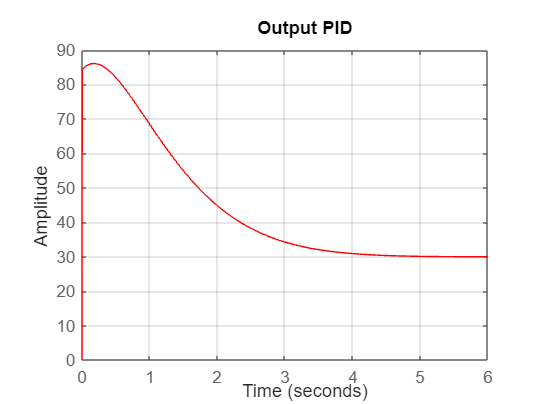

uc = 15;    % setpoint    
orde = 2;   % set orde=1 jika plant adalah orde 1
gain = 0.5; % gain plant
tau = 1;    % konstanta waktu orde-1
si = 1.707; % konstanta redaman orde-2
wn = 0.8;   % freq natural orde-2

T  = 0.05;  % waktu sampling
wc = 0.7;   % frekuensi crossover (rad/s)
gm = 40.0;  % gain margin

focus = 1;  % (1)tracking setpoint, (2) penolak gangguan, (3) antara 1&2 
if orde==1 G = tf(0.5, [1/tau 1]);
else G = tf(gain*wn*wn, [1 2*si*wn wn*wn]); end
focuses = ["reference-tracking","balanced", "disturbance-rejection"];
opts = pidtuneOptions('PhaseMargin', gmargin, 'DesignFocus', focuses(focus));
C = pidtune(G,'pid', wc, opts);
Gcs = feedback(C*G,1);
Gz = c2d(G,T,'zoh');
Cz = pidtune(Gz, 'pid', wc, opts);
Gcz = feedback(Cz*Gz,1);
M = uc*feedback(C*tf(1,[1e-5 1]),G);
step(M,'r-'), grid on, title('Output PID')

[m,t]=step(M); ax_m=max(m)

ax_m = 86.0689

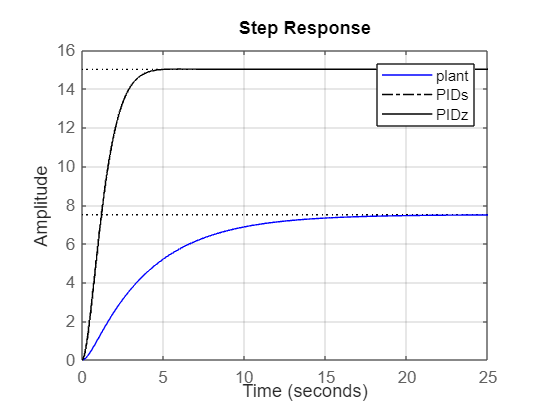

step(uc*G,'b-',uc*Gcs,'k-.', uc*Gcz,'k-'), grid on, legend('plant','PIDs','PIDz')

stepinfo([uc*Gz uc*Gcz])

ans = 1×2 struct array with fields:
    RiseTime
    TransientTime
    SettlingTime
    SettlingMin
    SettlingMax
    Overshoot
    Undershoot
    Peak
    PeakTime


display(Cz)

Cz =
 
              Ts            z-1 
  Kp + Ki * ------ + Kd * ------
              z-1           Ts  

  with Kp = 5.69, Ki = 1.46, Kd = 0.141, Ts = 0.05
 
Sample time: 0.05 seconds
Discrete-time PID controller in parallel form.
Model Properties
